# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF3_1_MachineLearning_Supervised

## Logistic Regression for Binary Classification

This example illustrated how **logistic regression** can be used for **binary classification** problems.

Starting from raw exam score data, we:

- explore and visualized the dataset,

- train a logistic regression model using `fitglm`,

- interpret the model coefficients to understand the impact of each variable,

- compute predicted probabilities and training accuracy, and

- visualize the **decision boundary** separating the two classes.

The fitted model provides a simple yet powerful way to **estimate probabilities of categorical outcomes** and to **visualize the separating surface** in the predictor space — a key idea that extends naturally to higher-dimensional classification problems and more advanced machine learning models.

Data

The data_classification.txt contains scores for two exams in addition to a binary variable which denotes whether students were admitted to a university. 

We obtain a logistic regression model to **predict admission probability **using the `fitglm` function. 

## Load the data into a `table` and preview the data

The first two columns (variables) will contain the exam scores and the third column the admission labels which we convert to `logical` values. 

We also compute some summary statistics on the three variables.

clear;
data = readtable('data_classification.xlsx');

data.Properties.VariableNames = {'Exam1','Exam2','Admitted'};

data.Admitted = logical(data.Admitted)

data = 88×3 table
    Exam1    Exam2    Admitted
    _____    _____    ________

     34       78       false  
     30       43       false  
     35       72       false  
     60       86       true   
     79       75       true   
     45       56       false  
     61       96       true   
     75       46       true   
     76       87       true   
     84       43       true   
     95       38       false  
     75       30       false  
     82       30       false  
     69       97       true   
     39       76       false  
     53       89       true   



summary(data)


data: 88×3 table

Variables:

    Exam1: double
    Exam2: double
    Admitted: logical (50 true)

Statistics for applicable variables:

             NumMissing     Min        Median        Max         Mean            Std    

    Exam1        0           30             67        99        65.2727        19.5093  
    Exam2        0           30        65.5000        98        64.2955        18.7673  



We create a **grouped scatter plot** of the two exam scores, using the variable `Admitted` to define the groups.

- Each point represents a student.

- The x-axis shows **Exam 1** scores and the y-axis shows **Exam 2** scores.

- MATLAB automatically assigns different colors or markers for the two groups (`Admitted = 1` and `Admitted = 0`).

This allows you to **visually separate admitted and non-admitted students** and observe whether a boundary between the two classes might exist in the exam-score space.

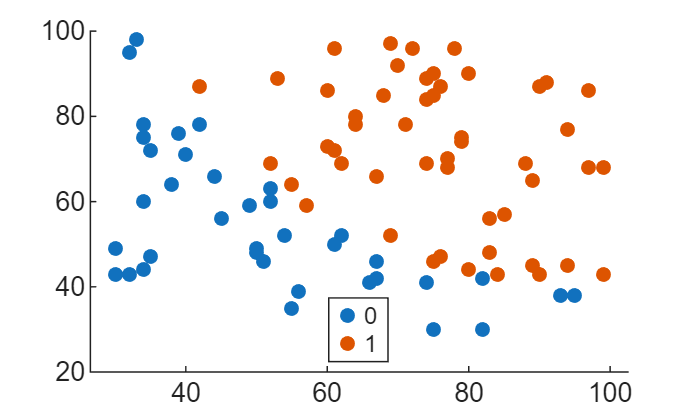

gscatter(data.Exam1,data.Exam2,data.Admitted)

We now plot the data manually to have full control over the style and prepare for adding the decision boundary.

Unlike **gscatter**, this approach lets us customize marker colors, sizes, and legend entries — using red circles for admitted students and yellow-filled blue circles for those not admitted.

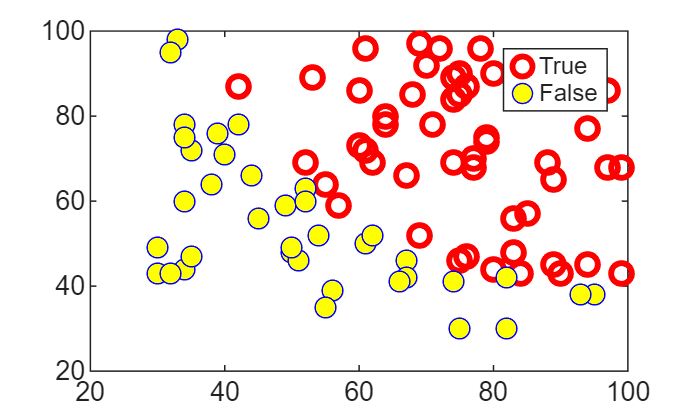

varNames = data.Properties.VariableNames;
% Plot the data with + for true and 0 for false examples
inds = data.(varNames{3}) == 1;
plot(data.(varNames{1})(inds), data.(varNames{2})(inds), 'ro','LineWidth', 2, 'MarkerSize', 7); 
inds = data.(varNames{3}) == 0;
hold on

plot(data.(varNames{1})(inds), data.(varNames{2})(inds), 'bo', 'MarkerFaceColor', 'y','MarkerSize', 7);
legend('True','False')
hold off

## Logistic Regression

We train the logistic regression model using the `fitglm` function, which fits a **generalized linear model** (GLM) to the data.

By setting the `'Distribution'` parameter to `'binomial'`, we specify that the response variable (`Admitted`) is **binary** — taking only the values 0 or 1.

This tells MATLAB to use the **logistic (logit) link function**, so the model estimates the **probability of admission** as a function of the two exam scores.

logMdl = fitglm(data,'Distribution','binomial')

logMdl = Generalized linear regression model:
    logit(Admitted) ~ 1 + Exam1 + Exam2
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -24.469       5.8101    -4.2115    2.5365e-05
    Exam1          0.20664     0.049113     4.2074    2.5835e-05
    Exam2          0.19073      0.04872     3.9147    9.0499e-05


88 observations, 85 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 83.4, p-value = 7.89e-19

Note the form of the model displayed in the output above. This is short-hand for 


$$\mathrm{logit}(Admitted) = 1*\theta_0+Exam1*\theta_1+Exam2*\theta_2$$
 

Since $\mathrm{logit}(x)$ is the* inverse function* of $\mathrm{sigmoid}(x)$, this model is equivalent to logistic regression model form for the probability of admission used in ex2: 

$Admitted = h_{\theta}(x) = \mathrm{sigmoid}(\theta^Tx)$,

where $x$ includes the two exam scores and a bias term. A bias term is added automatically by `fitglm`.

## Predict the training accuracy and probability of admission

Recall that a prediction of admission corresponds to a predicted probability > 0.5. Run the code below to extract the $\theta$ values from the trained model, predict the probability of admission, and compute the training accuracy. 

theta = logMdl.Coefficients.Estimate

theta =   -24.4693
    0.2066
    0.1907



% Predict the probability for a student with scores of 45 and 85

prob = predict(logMdl,[45 85]);

fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.739104



% Compute the training accuracy

Admitted = predict(logMdl,data) > 0.5;

fprintf('Train Accuracy: %f\n', mean(double(Admitted == data.Admitted)) * 100);

Train Accuracy: 88.636364


## Visualize the decision boundary 

Ceate a grid of exam scores and create the decision boundary plot. 

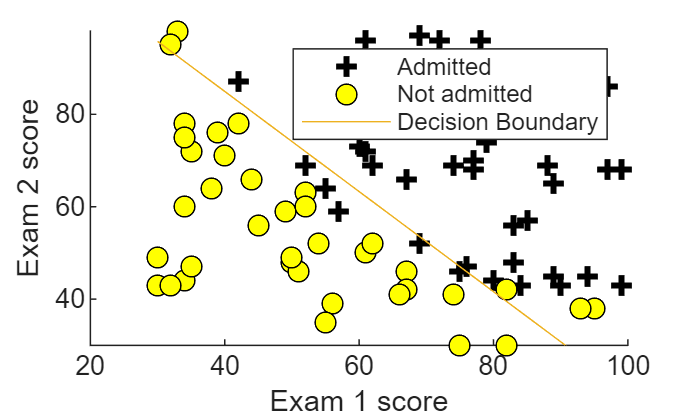

figure; hold on;
% Plot the positive and negative examples

varNames = data.Properties.VariableNames;
% Plot the data with + for true and 0 for false examples
inds = data.(varNames{3}) == 1;
plot(data.(varNames{1})(inds), data.(varNames{2})(inds), 'k+','LineWidth', 2, 'MarkerSize', 7); 
inds = data.(varNames{3}) == 0;


plot(data.(varNames{1})(inds), data.(varNames{2})(inds), 'ko', 'MarkerFaceColor', 'y','MarkerSize', 7);
% Plot the decision boundary
xvals = [min(data.Exam1), max(data.Exam1)];
yvals = -(theta(1)+theta(2)*xvals)/theta(3);
plot(xvals,yvals); hold off;
ylim([min(data.Exam2),max(data.Exam2)]);

% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
legend('Admitted','Not admitted','Decision Boundary')
hold off;

**Next Step – Exercise on Classification (Exam Scores)**

- Upload into the workspace the data contained into the spreadsheet data_classification.xlsx

- In the MATLAB Apps tab, select the Classification Learner app from the Machine Learning section

- Select 'New Session -> From Workspace' to start

- Under 'Workspace Variable', select 'data' and you will automatically find Exam1 and Exam2

- The app should correctly detect Admitted as the response variable to predict.

- Choose the default validation option.

- Select a model  (e.g., logistic regression, decision tree, or SVM) and click the **Train** button.

- Experiment with several standard models using default settings and see if you can achieve at least 80% accuracy.

**This exercise helps you compare the manual logistic regression workflow with MATLAB's interactive machine learning tools, reinforcing how supervised learning models can be trained and evaluated in different ways.**